clear 
clc
syms x
X=[0 1 3 4 6 7 ]

X =      0     1     3     4     6     7


Y=[-5 1 25 55 181 289]

Y =     -5     1    25    55   181   289





% X=[0 1 3 4 6 7]
% Y=[-5 1 25 55 181 289]
  

nn={'y';'y'};
dd={'y' 'y'};
L_n=str2sym( nn);
L_d=str2sym(dd);

num = length(Y);
num2 = length(Y);



    
for j=1:num
 C = nchoosek(X,num-1);         
   numerador = x-C(j,:);    
      bb = expand(prod(numerador));         
            L_n(j) = bb   ;      
end      

     
for k=1:num         

   D = flipud(nchoosek(X,num-1)  );
     denominador = X(k)-D(k,:);
          cc =  prod(denominador);
               L_d(k) = cc    ;                                             
end
     
nume =  L_n  

$$nume = \left(\begin{array}{c} x^{5}-14\,x^{4}+67\,x^{3}-126\,x^{2}+72\,x\\ x^{5}-15\,x^{4}+75\,x^{3}-145\,x^{2}+84\,x\\ x^{5}-17\,x^{4}+97\,x^{3}-207\,x^{2}+126\,x\\ x^{5}-18\,x^{4}+111\,x^{3}-262\,x^{2}+168\,x\\ x^{5}-20\,x^{4}+145\,x^{3}-450\,x^{2}+504\,x\\ x^{5}-21\,x^{4}+165\,x^{3}-595\,x^{2}+954\,x-504 \end{array}\right)$$

deno =  (flipud(L_d') )  

$$deno = \left(\begin{array}{c} 504\\ -180\\ 72\\ -72\\ 180\\ -504 \end{array}\right)$$

lagrange =simplify(flipud(nume./deno)  )

$$lagrange = \left(\begin{array}{c} -\frac{x^{5}}{504}+\frac{x^{4}}{24}-\frac{55\,x^{3}}{168}+\frac{85\,x^{2}}{72}-\frac{53\,x}{28}+1\\ \frac{x\,\left(x^{4}-20\,x^{3}+145\,x^{2}-450\,x+504\right)}{180}\\ -\frac{x\,\left(x^{4}-18\,x^{3}+111\,x^{2}-262\,x+168\right)}{72}\\ \frac{x\,\left(x^{4}-17\,x^{3}+97\,x^{2}-207\,x+126\right)}{72}\\ -\frac{x\,\left(x^{4}-15\,x^{3}+75\,x^{2}-145\,x+84\right)}{180}\\ \frac{x\,\left(x^{4}-14\,x^{3}+67\,x^{2}-126\,x+72\right)}{504} \end{array}\right)$$


final_lagrange =simplify(sum(Y'.*lagrange)) 

$$final\_lagrange = x^{3}-2\,x^{2}+7\,x-5$$


char(final_lagrange)

ans = '7*x - 2*x^2 + x^3 - 5'

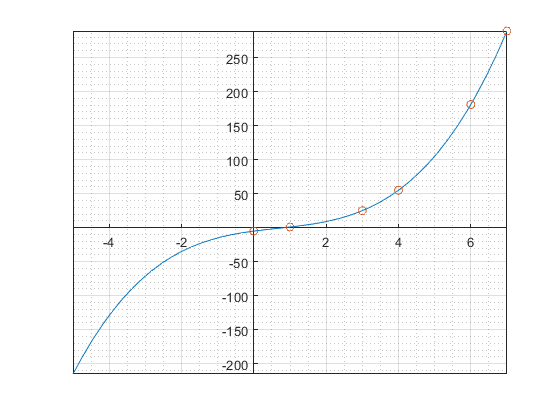


fplot(final_lagrange);
grid on;
grid minor
hold on;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

plot(X,Y,'o')


x=8

x =      8


eval(final_lagrange)

ans =    435

 PRIMER EJEMPLO 

X=[0 1 2 3]

Y=[-1 6 31 18]

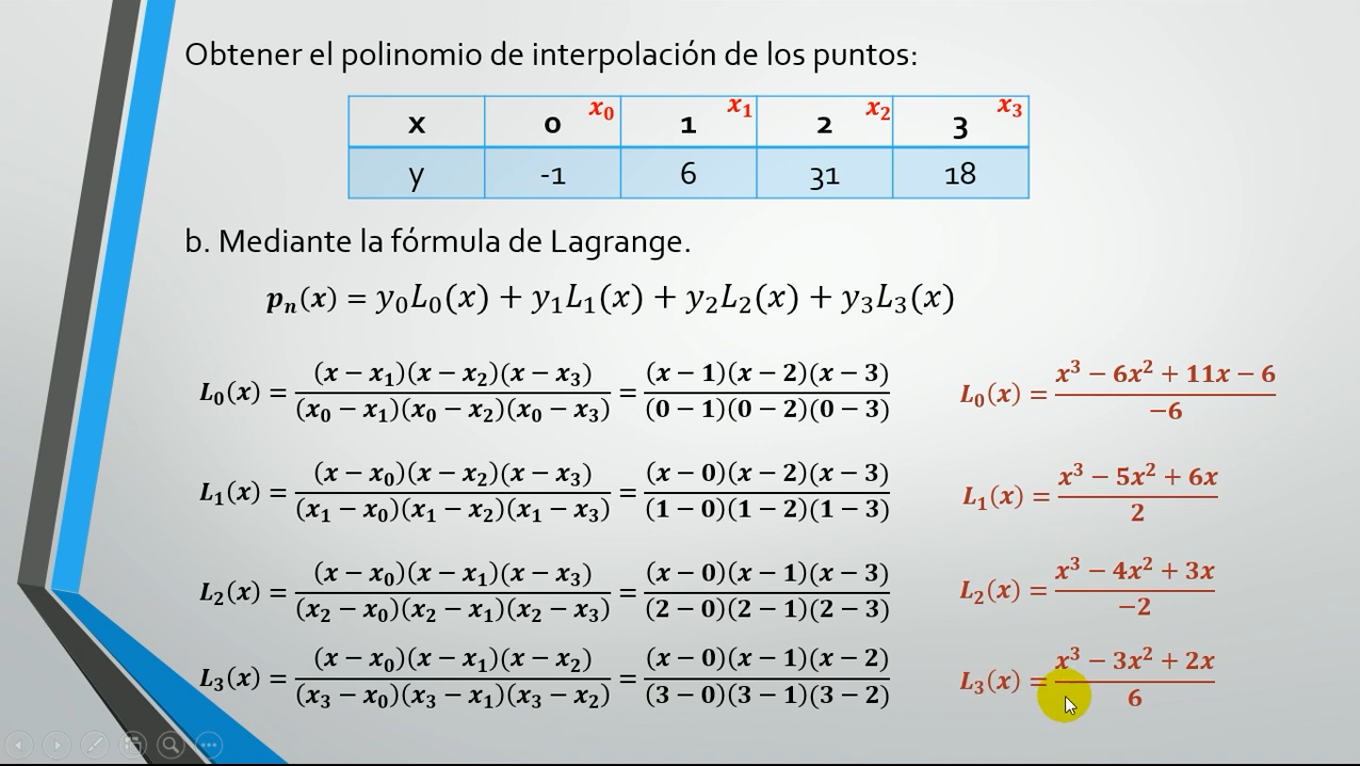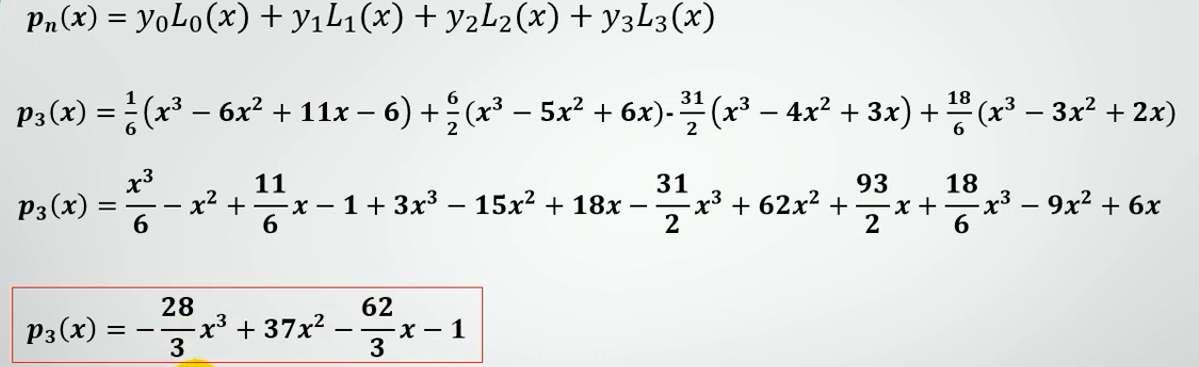

% C = nchoosek(X,3)
% aa=x-C(1,:)
% expand(prod(aa))
% sum(aa)

SEGUNDO EJEMPLO

X=[2 2.75 4]

Y=[1/2 1/2.75 1/4]